clear;

num_samples = 1200;
fs = 12000;

data_path = 'F:\Dateset\CWRU'; % 数据集路径

cls_1 = '12K_DE_Normal/'; 
cls_2 = '12k_DE_IRFault_0.007/';   
cls_3 = '12k_DE_IRFault_0.014/';   
cls_4 = '12k_DE_IRFault_0.021/'; 
cls_5 = '12k_DE_BallFault_0.007/';  
cls_6 = '12k_DE_BallFault_0.014/'; 
cls_7 = '12k_DE_BallFault_0.021/';
cls_8 = '12k_DE_ORFault_0.007/';   
cls_9 = '12k_DE_ORFault_0.014/';   
cls_10 ='12k_DE_ORFault_0.021/';

norm_path = fullfile(data_path, cls_1);
defc1_path = fullfile(data_path, cls_2);
defc2_path = fullfile(data_path, cls_3);
defc3_path = fullfile(data_path, cls_4);
defc4_path = fullfile(data_path, cls_5);
defc5_path = fullfile(data_path, cls_6);
defc6_path = fullfile(data_path, cls_7);
defc7_path = fullfile(data_path, cls_8);
defc8_path = fullfile(data_path, cls_9);
defc9_path = fullfile(data_path, cls_10);

[norm, y_norm] = make_dataset(norm_path, num_samples, 1);
[defc1, y_defc1] = make_dataset(defc1_path, num_samples, 2);
[defc2, y_defc2] = make_dataset(defc2_path, num_samples, 3);
[defc3, y_defc3] = make_dataset(defc3_path, num_samples, 4);
[defc4, y_defc4] = make_dataset(defc4_path, num_samples, 5);
[defc5, y_defc5] = make_dataset(defc5_path, num_samples, 6);
[defc6, y_defc6] = make_dataset(defc6_path, num_samples, 7);
[defc7, y_defc7] = make_dataset(defc7_path, num_samples, 8);
[defc8, y_defc8] = make_dataset(defc8_path, num_samples, 9);
[defc9, y_defc9] = make_dataset(defc9_path, num_samples, 10);

X = [norm; defc1; defc2; defc3; defc4; defc5; defc6; defc7; defc8; defc9];
Y = [y_norm; y_defc1; y_defc2; y_defc3; y_defc4; y_defc5; y_defc6; y_defc7; y_defc8; y_defc9];

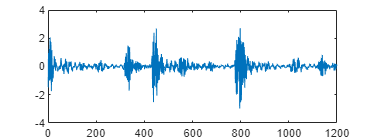

figure('Position', [100, 100, 800, 300]); % 创建一个新的图形窗口并设置尺寸
plot(defc9(1,:)); % 绘制数据

% wavelet_function = 'db4';
% num_levels = 3; 
% m = 1; 
% 
% num_features = 2^num_levels;
% features = nan(size(X, 1), m*num_features);
% 
% for i = 1:size(X, 1)
%     wp = wpdec(X(i, :), num_levels, wavelet_function); % Wavelet packet transformation
%     packet_names = wp.tree;
%     for j = 1:num_features
%         new_wp = wpdec(X(i,:), num_levels, wavelet_function);
%         new_wp.tree = packet_names(j);
%         reconstructed_signal = wprec(new_wp); % Signal reconstruction from wavelet packet coefficients
%         [f, c] = apply_fft(reconstructed_signal, fs, length(reconstructed_signal));
%         z = abs(c);
%         
%         [~, maximal_idx] = maxk(z, m);
%         high_amp = z(maximal_idx);
%         high_freq = f(maximal_idx);
%         feature = high_amp.*high_freq;
%         
%         l = 0;
%         for f = feature
%             features(i,j*m+l) = f;
%             l = l+1;
%         end
%     end
% end

clear;

%% 划分测试集和训练集


data = load('seeds_dataset.txt'); 
Data = data(:, 1:end-1);
labels = data(:, end);

% 划分[trainInd,valInd,testInd] = dividerand(Q,trainRatio,valRatio,testRatio)
[trainInd,valInd,testInd] = dividerand(size(data, 1), 0.8, 0, 0.2);

X_train = Data(trainInd); Y_train = labels(trainInd);
X_test = Data(testInd); Y_test = labels(testInd);
% labels = pd.Categorical(Y)
% X_train, X_test, Y_train, Y_test = train_test_split(features, labels, test_size = 0.2, 
%                                             stratify = labels, random_state = 42)

% 归一化
[X_train_scaled, C, S] = normalize(X_train, 'zscore');
X_test_scaled = normalize(X_test,"center",C,"scale",S);
